##  Задание 1. Исследование управляемости. 

Начальные условия на задание:

A = [3, -6, 4; 
     4, -5, 4;
     -4, 4, -5];
B = [-1;
      3;
      1];
x1 = [1;
      0;
      0];

Исследовать управляемость системы по трём критерям:

Проверка критерия Калмана

U = [B , A*B , A^2 * B]

U =     -1   -17    83
     3   -15    51
     1    11   -47


rank(U)

ans = 3

Проверка критерия Хаутуса:

eig(A)

ans =   -3.0000 + 2.0000i
  -3.0000 - 2.0000i
  -1.0000 + 0.0000i


l1 = -3 + 2j; l2 = -3 - 2j; l3 = -1;

[A - eye(3).*l1 , B]

ans =    6.0000 - 2.0000i  -6.0000 + 0.0000i   4.0000 + 0.0000i  -1.0000 + 0.0000i
   4.0000 + 0.0000i  -2.0000 - 2.0000i   4.0000 + 0.0000i   3.0000 + 0.0000i
  -4.0000 + 0.0000i   4.0000 + 0.0000i  -2.0000 - 2.0000i   1.0000 + 0.0000i


[A - eye(3).*l2 , B]

ans =    6.0000 + 2.0000i  -6.0000 + 0.0000i   4.0000 + 0.0000i  -1.0000 + 0.0000i
   4.0000 + 0.0000i  -2.0000 + 2.0000i   4.0000 + 0.0000i   3.0000 + 0.0000i
  -4.0000 + 0.0000i   4.0000 + 0.0000i  -2.0000 + 2.0000i   1.0000 + 0.0000i


[A - eye(3).*l3 , B]

ans =      4    -6     4    -1
     4    -4     4     3
    -4     4    -4     1



rank([A - eye(3).*l1 , B])

ans = 3

rank([A - eye(3).*l2 , B])

ans = 3

rank([A - eye(3).*l3 , B])

ans = 3

Проверка критерия по Жордану (функция в матлабе немного криво реализована):

[P, Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P, Aj);

Aj2  % теперь их соотносим

Aj2 =     -1     0     0
     0    -3    -2
     0     2    -3


P^-1 * B    % теперь их соотносим

ans =    4.0000 + 0.0000i
  -1.5000 + 1.5000i
  -1.5000 - 1.5000i


- Все Жордановы клетки относятся к различным собственными числам - ДА

- Элементы матрицы входных воздействий, соответствующие последним строкам жордановых клеток не равны 0.

Собственное число -1 --> **да**, ведь там 4.00 стоит

Собственное число комплексное --> 

"Для комплексных не кратных можно  управлять Жордановой  клеткой хоть через  верхнюю строку, хоть  через нижнюю, система  все еще управляема"

И  ответ будет **да**, и там и там -2.1 стоит...

Всё выполняется, а значит система в жордановой форме **полностью управляема**

Найти Грамиан...

Считаем Граммиан по определению

t1 = 3;

syms t
expr = expm(A*t) * B * (B.') * expm( (A.') * t)

F = int(expr,t, [0 t1])

$$F = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\mathrm{e}}^{-18}\,\left(153\,\cos\left(12\right)-416\,{\mathrm{e}}^{12}+458\,{\mathrm{e}}^{18}+54\,\sin\left(12\right)-624\,{\mathrm{e}}^{6}\,\sin\left(6\right)-195\right)}{52} & \sigma_{2} & \sigma_{3}\\ \sigma_{2} & \frac{3\,{\mathrm{e}}^{-18}\,\left(6\,\cos\left(12\right)+7\,{\mathrm{e}}^{18}+9\,\sin\left(12\right)-13\right)}{26} & \sigma_{1}\\ \sigma_{3} & \sigma_{1} & \frac{{\mathrm{e}}^{-18}\,\left(90\,\cos\left(12\right)-1040\,{\mathrm{e}}^{12}+833\,{\mathrm{e}}^{18}+135\,\sin\left(12\right)+\sigma_{4}-936\,{\mathrm{e}}^{6}\,\sin\left(6\right)-195\right)}{130} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{3\,{\mathrm{e}}^{-18}\,\left(30\,\cos\left(12\right)-17\,{\mathrm{e}}^{18}+45\,\sin\left(12\right)+52\,\cos\left(6\right)\,{\mathrm{e}}^{6}-156\,{\mathrm{e}}^{6}\,\sin\left(6\right)-65\right)}{130}\\ \sigma_{2}=\frac{3\,{\mathrm{e}}^{-18}\,\left(135\,\cos\left(12\right)-44\,{\mathrm{e}}^{18}+105\,\sin\left(12\right)+104\,\cos\left(6\right)\,{\mathrm{e}}^{6}-312\,{\mathrm{e}}^{6}\,\sin\left(6\right)-195\right)}{260}\\ \sigma_{3}=-\frac{{\mathrm{e}}^{-18}\,\left(405\,\cos\left(12\right)-2080\,{\mathrm{e}}^{12}+1948\,{\mathrm{e}}^{18}+315\,\sin\left(12\right)+\sigma_{4}-2496\,{\mathrm{e}}^{6}\,\sin\left(6\right)-585\right)}{260}\\ \sigma_{4}=312\,\cos\left(6\right)\,{\mathrm{e}}^{6} \end{array}$$

integral_cutted = double(vpa(F)) 

integral_cutted =     8.7879   -0.5077   -7.4725
   -0.5077    0.8077    0.3923
   -7.4725    0.3923    6.3879


eig_values_gram = eig(integral_cutted)

eig_values_gram =     0.0184
    0.7804
   15.1847


Попробуем конкретной функцией получим Граммиан

C = zeros([1, 3]); D = zeros([1, 1]);
sys = ss(A,B,C,D)

sys =
 
  A = 
       x1  x2  x3
   x1   3  -6   4
   x2   4  -5   4
   x3  -4   4  -5
 
  B = 
       u1
   x1  -1
   x2   3
   x3   1
 
  C = 
       x1  x2  x3
   y1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


control_gram = gram(sys, 'c')

control_gram =     8.8077   -0.5077   -7.4923
   -0.5077    0.8077    0.3923
   -7.4923    0.3923    6.4077


observe_gram = gram(sys, 'o');
eig_values_gram = eig(control_gram)

eig_values_gram =     0.0186
    0.7805
   15.2240


Мы получили, что все С.Ч. - положительны, а это автоматически значит то, что матрица Грамиана управляемости положительно определена, а значит выполняется критерий - " Грамиан управляемости – положительно  определенная матрица для любых 𝑡;" - Система управляема.

Найти управление, выполнить моделирование по нему

time = linspace(0, t1, 1000);
u_values = zeros(size(time)); 
t_values = zeros(3, length(time)); 

(B.') * expm((A.') * (t1 - t)) * (integral_cutted^-1) * x1

$$ans = \frac{536048852474409\,{\mathrm{e}}^{t-3}}{35184372088832}+{\mathrm{e}}^{t\,\left(3-2\,\mathrm{i}\right)-9+6\,\mathrm{i}}\,\left(-\frac{16080272106541743}{4503599627370496}+\frac{138950454232648857}{4503599627370496}\,\mathrm{i}\right)+{\mathrm{e}}^{t\,\left(3+2\,\mathrm{i}\right)-9-6\,\mathrm{i}}\,\left(-\frac{16080272106541743}{4503599627370496}-\frac{138950454232648857}{4503599627370496}\,\mathrm{i}\right)$$

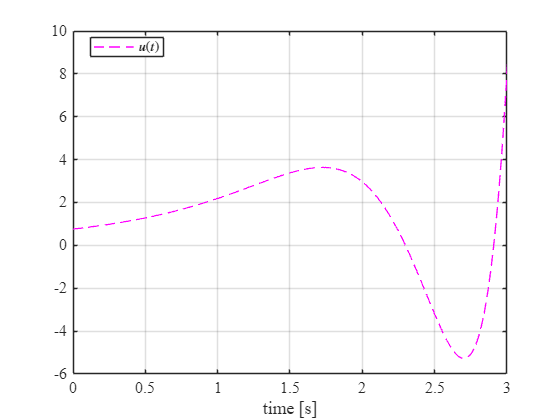


u = @(t) (B.') * expm((A.') * (t1 - t)) * (integral_cutted^-1) * x1;

for i = 1:length(time)
    u_values(i) = u(time(i));
end

expmA = @(t) expm(A * (t1 - t) ) * B * u(t);

for i = 1:length(time)
    t_values(:, i) = integral(expmA, 0 , time(i), 'ArrayValued',true); 
end

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, u_values, 'magenta--', 'LineWidth', 1.0); 
title(' ');
xlabel('time [s]');                  
grid on;
legend('$u(t)$', 'Location', 'best', 'Interpreter', 'latex');
save_file("control1");
xlim([0.0, 3.0])

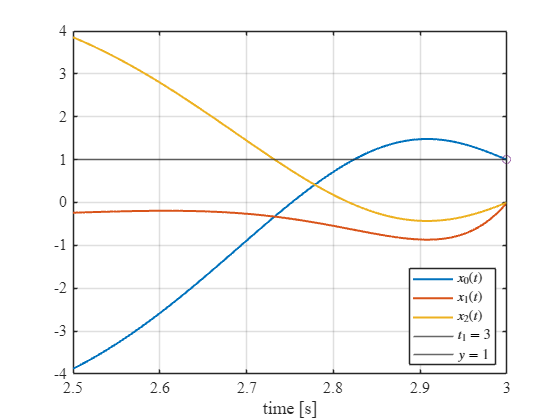

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
plot(time, t_values(1, :), 'LineWidth', 1.5); hold on;
plot(time, t_values(2, :), 'LineWidth', 1.5);
plot(time, t_values(3, :), 'LineWidth', 1.5);
xline(3, '-'); yline(1, '-'); plot(3, 1, 'o')
title(' ');   
xlabel('time [s]');                  
grid on;
legend('$x_0(t)$', '$x_1(t)$', '$x_2(t)$', '$t_1 = 3$', '$y = 1$', ...
       'Location', 'best', 'Interpreter', 'latex');
xlim([2.5, 3.0])
save_file("controlability1");

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab7\latex7\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end